% load animal data
clear

AnimalID = "SP25"

AnimalID = "SP25"


ExperimentFolder = "Pf_Caspase_Experiment"

ExperimentFolder = "Pf_Caspase_Experiment"


% Set input folder

InputDirectory = "/media/sthitapati/D/Behavioural_Data/matlab_output";


InputFolder = strcat(InputDirectory, "/", ExperimentFolder, "/",AnimalID)

InputFolder = "/media/sthitapati/D/Behavioural_Data/matlab_output/Pf_Caspase_Experiment/SP25"

% check if the file to be analyzed exists

GetDir = dir(InputFolder);

if isempty(GetDir)
    disp("There is no data to analyze: Go back to data curation");
end

file_query = dir(strcat(InputFolder, "/*.mat"));

if ~isempty(file_query) && contains(file_query.name, AnimalID)
    load(strcat(InputFolder, "/matlab_output_", AnimalID, ".mat"));
else
    disp("There is no data to analyze: Go back to data curation");
end

head(bpodTable)

ans = 8×27 table
    AnimalID         Experiment          SessionDate    SessionTime          DateTime           Protocol       Stimulation     Muscimol    RewardChangeBlock    CenterPortDuration    Contingency       ContingencyBlock        RewardAmount    TrialIndex    TrialHighPerc    Outcomes    OptoStim    FirstPokeCorrect    FirstPoke    TrialSide    TrialSequence    TResponseTime    TrialStartTimeStamp    TrialEndTimestamp    CumulativePerformance    PreviousChoice    SwitchSide
    ________    __________

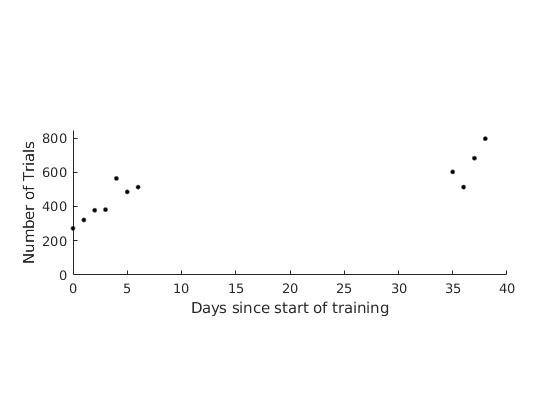

% Plot training day in X-axis and Number of trials in Y-axis
% TODO: Specification and beautification of plot

T = rowfun(@max, bpodTable, "InputVariables", "TrialIndex", "GroupingVariables", "DateTime", "OutputVariableNames", "number_of_trials");
T_duration = T.DateTime - T.DateTime(1);
T_duration = round(days(T_duration));
figure(1)
hold on
plot(T_duration, T.number_of_trials, '.k', "MarkerSize", 10)
pbaspect([3 1 1])

xlabel("Days since start of training")
ylabel("Number of Trials")
ylim([0, max(T.number_of_trials) + 50])

hold off

% Choose only Visual trials
VisTrials = bpodTable(bpodTable.Protocol == "Visual", ...
    {'TrialHighPerc', 'FirstPoke', 'DateTime', 'Stimulation', 'SessionDate', 'Contingency'})

VisTrials = 4439×6 table
    TrialHighPerc    FirstPoke          DateTime           Stimulation     SessionDate    Contingency
    _____________    _________    ____________________    _____________    ___________    ___________

          2               1       16-Feb-2021 11:24:21    NoStimulation    16-Feb-2021        -1     
          2             NaN       16-Feb-2021 11:24:21    NoStimulation    16-Feb-2021        -1     
          2               2       16-Feb-2021 11:24:21    NoStimulation    16-Feb-2021        -1     
         98               1       16-Feb-2021 11:24:21    NoStimulation    16-Feb-2021        -1     
          2               1       16-Feb-2021 11:24:21    NoStimulation    16-Feb-2021        -1     
         98               2       16-Feb-2021 11:24:21  

PerformanceTable = rowfun(@measurePerformance, VisTrials, ...
    "InputVariables", ["FirstPoke", "Contingency"], ...
    "GroupingVariables", "SessionDate", ...
    "OutputVariableNames",["RightChoice", "Total", "PercentCorrect", "PercentRight"])

PerformanceTable = 9×6 table
    SessionDate    GroupCount    RightChoice    Total    PercentCorrect    PercentRight
    ___________    __________    ___________    _____    ______________    ____________

    16-Feb-2021       321             73         321        0.77259          0.22741   
    17-Feb-2021       378            164         378        0.56614          0.43386   
    18-Feb-2021       381            180         381        0.52756          0.47244   
    19-Feb-2021       564            273         564        0.51596          0.48404   
    20-Feb-2021       485            234         485        0.51753          0.48247   
    21-Feb-2021       513            248         513        0.51657          0.48343   
    22-Mar-2021       602            258         602        0.



% all_sessions = unique(PerformanceTable.DateTime);

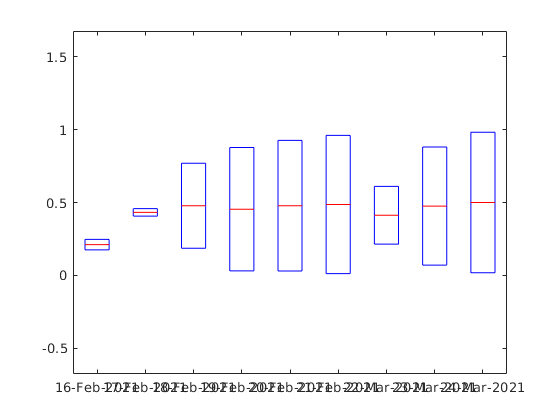


g(PerformanceTable.PercentRight, PerformanceTable.SessionDate)

% Choose only Auditory trials
% Only extract variables that are to be used
AudTrials = bpodTable(bpodTable.Protocol == "Auditory", ...
    {'TrialHighPerc', 'FirstPoke', 'SessionDate','DateTime','Contingency'})

AudTrials = 796×5 table
    TrialHighPerc    FirstPoke    SessionDate          DateTime          Contingency
    _____________    _________    ___________    ____________________    ___________

         98               2       25-Mar-2021    25-Mar-2021 11:46:05        -1     
         98               1       25-Mar-2021    25-Mar-2021 11:46:05        -1     
         98             NaN       25-Mar-2021    25-Mar-2021 11:46:05        -1     
          2               2       25-Mar-2021    25-Mar-2021 11:46:05        -1     
          2               1       25-Mar-2021    25-Mar-2021 11:46:05        -1     
         98               2       25-Mar-2021    25-Mar-2021 11:46:05        -1     
          2               1       25-Mar-2021    25-Mar-2021 11:46:05        -1     
         98               1       25-Mar

PerformanceTable = rowfun(@measurePerformance, AudTrials, ...
    "InputVariables", ["FirstPoke", "Contingency"], ...
    "GroupingVariables",["TrialHighPerc", "DateTime"], ...
    "OutputVariableNames",["RightChoice", "Total", "PercentCorrect", "PercentRight"])

PerformanceTable = 2×7 table
    TrialHighPerc          DateTime          GroupCount    RightChoice    Total    PercentCorrect    PercentRight
    _____________    ____________________    __________    ___________    _____    ______________    ____________

          2          25-Mar-2021 11:46:05       392            176         392        0.55102          0.44898   
         98          25-Mar-2021 11:46:05       404            202         404            0.5              0.5   




all_sessions = unique(PerformanceTable.DateTime);

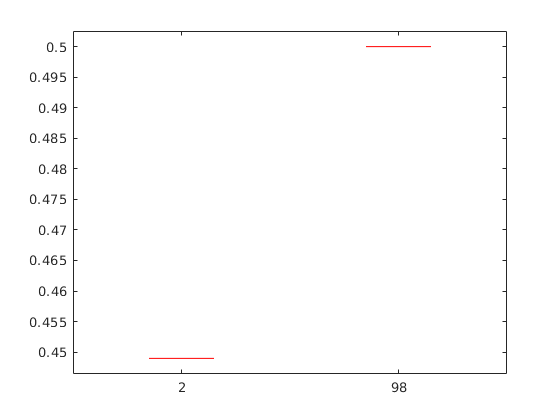

% plot high/ low vs performance

boxplot(PerformanceTable.PercentRight, PerformanceTable.TrialHighPerc)

% Visualize in matrix plot

% plot percent correct by session

% plot session vs cumulative performance

T3 = bpodTableAll(bpodTableAll.AnimalID == "SP19", "CumulativePerformance")

Unable to resolve the name bpodTableAll.AnimalID.

sm = smoothdata(T3.CumulativePerformance, "SmoothingFactor", 0.03)

plot(sm, "o","LineStyle","none", "MarkerSize", 1)
ylim([0, 120])

% plot session vs rightbias

% Choose only psychometric trials

PsychTrials = bpodTable(bpodTable.Protocol == "Aud_Psycho", ...
    {'TrialHighPerc', 'FirstPoke', 'DateTime', 'Stimulation', 'Contingency'})

PsychTrials = 15315×5 table
    TrialHighPerc    FirstPoke          DateTime           Stimulation     Contingency
    _____________    _________    ____________________    _____________    ___________

          2              2        08-Dec-2020 16:11:07    NoStimulation         1     
          2              2        08-Dec-2020 16:11:07    NoStimulation         1     
          2              2        08-Dec-2020 16:11:07    NoStimulation         1     
         82              1        08-Dec-2020 16:11:07    NoStimulation         1     
          2              2        08-Dec-2020 16:11:07    NoStimulation         1     
         18              2        08-Dec-2020 16:11:07    NoStimulation         1     
         50              1        08-Dec-2020 16:11:07    NoStimulation         1     
         18       


% TODO write a function handle to extract desired sessions when given
% datetime values as inputs
% PsychTrials_exctracted = PsychTrials(PsychTrials.DateTime == {'08-Dec-2020 16:11:07','09-Dec-2020 13:40:19'}, :)


% Plot TrialHighPerc in x-axis as categories and percent right choice in y-axis
% calculate % right choice
% 1 is left 2 is right

% Prepare table for plotting

PerformanceTable = rowfun(@measurePerformance, PsychTrials, ...
    "InputVariables", ["FirstPoke","Contingency"], ...
    "GroupingVariables",["TrialHighPerc", "DateTime"], ...
    "OutputVariableNames",["RightChoice", "Total", "PercentCorrect", "PercentRight"])

PerformanceTable = 217×7 table
    TrialHighPerc          DateTime          GroupCount    RightChoice    Total    PercentCorrect    PercentRight
    _____________    ____________________    __________    ___________    _____    ______________    ____________

          2          08-Dec-2020 16:11:07        63            58           63        0.92063          0.92063   
          2          09-Dec-2020 13:40:19        35            27           35        0.77143          0.77143   
          2          10-Dec-2020 16:08:54        61            60           61        0.98361          0.98361   
          2          11-Dec-2020 16:00:47        87            77           87        0.88506          0.88506   
          2          14-Dec-2020 15:32:58     



all_sessions = unique(PerformanceTable.DateTime);

% Fit to logistic regression


range_for_logitFit = 0:1:100;
[logitCoef, dev, stats] = glmfit(PerformanceTable.TrialHighPerc, [PerformanceTable.RightChoice, PerformanceTable.Total] , ...
    "binomial", "link", "logit");
[logitFit, dylo, dyhi] = glmval(logitCoef, range_for_logitFit, "logit", stats, "confidence", 0.95);
err = [dylo, dyhi];

% Make figures
num_col = 4;
M = mod(length(all_sessions), 4);
rows = ceil((length(all_sessions) + M)/ num_col);

figure(2);
figure("Position", [1, 1, 2400, 2400]);

for i = 1: length(all_sessions)
        P1 = PerformanceTable(PerformanceTable.DateTime == all_sessions(i), :);
        range_for_logitFit = 0:1:100;
        [logitCoef, dev, stats] = glmfit(P1.TrialHighPerc, [P1.RightChoice, P1.Total] , ...
                                    "binomial", "link", "logit");
        [logitFit, dylo, dyhi] = glmval(logitCoef, range_for_logitFit, "logit", stats, "confidence", 0.95);
                                        err = [dylo, dyhi];
    
        s = subplot(rows, num_col, i);
        plot_title = string(datestr(datenum(all_sessions(i))));
        plot_title = extractBefore(plot_title, " ");
        
        PlotPsychFunction(P1.TrialHighPerc, P1.PercentRightChoice, ...
                            range_for_logitFit, logitFit,dylo, dyhi);
        title(plot_title, "FontSize", 8, "FontWeight","normal");
        pbaspect([1.4 1 1]);
end





% bootstrap and plot crossvalidated models
% TODO: Write a function to plot with boostrapping

figure(3);

figure("Position", [1, 1, 2400, 2400]);
for i = 1: length(all_sessions)
        P1 = PerformanceTable(PerformanceTable.DateTime == all_sessions(i), :);
        range_for_logitFit = 0:1:100;
        [logitCoef, dev, stats] = glmfit(P1.TrialHighPerc, [P1.RightChoice, P1.Total] , ...
                                    "binomial", "link", "logit");
        [logitFit, dylo, dyhi] = glmval(logitCoef, range_for_logitFit, "logit", stats, "confidence", 0.95);
                                        err = [dylo, dyhi];
    
        s = subplot(rows, num_col, i);
        plot_title = string(datestr(datenum(all_sessions(i))));
        plot_title = extractBefore(plot_title, " ");
        
        PlotPsychFunctionBtStrp(P1.TrialHighPerc, P1.PercentRightChoice, ...
                            range_for_logitFit, logitFit,dylo, dyhi);
        title(plot_title, "FontSize", 8, "FontWeight","normal");
        
        pbaspect([1.4 1 1]);
end


% Make a matrix of psychometric plots for each session of the animals
% accumulate as sessions as columns and difficulty as rows
%TODO: Write a function for Matrix plots

untr = unique(PerformanceTable.TrialHighPerc);
undt = unique(PerformanceTable.DateTime);
PsychMat = zeros(length(untr), length(undt));
for i = 1:length(untr)
    PsychMat(i,:) = PerformanceTable.PercentRightChoice(PerformanceTable.TrialHighPerc == untr(i));
end




% Write a code to subplot categorical description on top of the plot
% make an array of optostim values in a particular session

Sessions = string(datestr(datenum(undt)));

catTable = table();
warning("off")
for i =1:length(Sessions)
    catTable.Session(i) = Sessions(i);
    idx = find(PsychTrials.DateTime == Sessions(i));
    catTable.Stim(i) = unique(PsychTrials.Stimulation(idx));
    catTable.Muscimol(i) = unique(PsychTrials.Muscimol(idx));
end


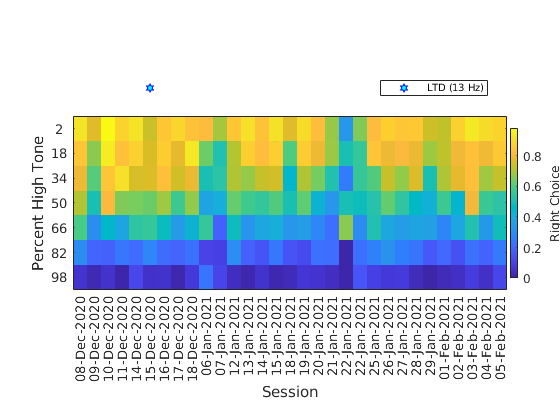

Sessions_label = extractBefore(Sessions, " ");
A = zeros(1, length(catTable.Stim));
for i = 1: length(catTable.Stim)
    if catTable.Stim(i) == "Both"
        A(1, i) = 1;
    else
        A(1, i) = 0;
    end
end

A(A == 0) = NaN;
figure(4);
%% TODO Automate ax2 positioning so that it can be used within a loop
ax1 = axes('Position',[0.13 0.75 0.7750 0.08]);
ax2 = axes('Position',[0.13 0.11 0.7750 0.8150]);

% linkaxes([ax1 ax2], 'xy')

imagesc(ax2, PsychMat);
ax2.PlotBoxAspectRatio = [2 0.8 1];

xlabel("Session");
ylabel("Percent High Tone");
ax2.XTick = (1:size(PsychMat, 2)) ;
ax2.YTick = (1:size(PsychMat, 1)) ;
ax2.XTickLabel = Sessions_label';
ax2.YTickLabel = untr;
ax2.XTickLabelRotation = 90;

cb = colorbar(ax2);
cb.Position = [0.91 0.3381 0.015 0.357]; 
cb.Label.String = "Right Choice";


xAx = ax2.XAxis;
xAx.TickLength = [0 0];

yAx = ax2.YAxis;
yAx.TickLength = [0.004 0];

X = 1: length(A);
s = scatter(ax1, X, A);
s.Marker = "hexagram";
s.MarkerFaceColor = "c";
s.MarkerEdgeColor = "b";

          
ax1.XLim = [0.5 length(A)+0.5];
ax1.XAxis.Visible = "off";
ax1.YAxis.Visible = "off";
xlabel(ax1, "none");
ylabel(ax1, "none");
legend(ax1, "LTD (13 Hz)", "Location", "best");

% Plot Cumulative performace across all trials, individual sessions to be
% color coded
% Plot Right bias across all sessions
% Bar graph showing session time in X-axis and percent correct Y-axis
% Split data for conditions: e.g. Pf leison

% Function definitions

function [RightCount, Total, PercentCorrect, PercentRight] = measurePerformance(FirstPoke, Contingency)
    RightCount = nnz(FirstPoke == 2);
    Total = numel(FirstPoke);
    PercentRight = RightCount ./ Total;
    if Contingency == 1
          
        PercentCorrect = RightCount ./ Total;
                
    elseif Contingency == -1
        
        PercentCorrect = 1 - (RightCount ./ Total);
        
    end
end

% Function to bootstrap and fit to a logistic regression
function bfit = glmBfit(diff, perf)

bfit = glmfit(diff, perf, "binomial", "link","logit");

end


% Function to plot the data

function PlotPsychFunction(difficulty, performance,range_for_logitFit, logitFit,dylo, dyhi)

ax = gca;

hold on

plot(difficulty, performance, "ob", "MarkerFaceColor", "b")
plot(range_for_logitFit, logitFit, "k-")
plot(range_for_logitFit, logitFit - dylo, "r--")
plot(range_for_logitFit, logitFit + dyhi, "r--")

xlabel("Percent High Tone");
ylabel ("Right Choice");
xtickangle(45);

ax.XTick = difficulty;

xAx = ax.XAxis;
xAx.Direction = "reverse";
hold off

end

function PlotPsychFunctionBtStrp(difficulty, performance,range_for_logitFit, logitFit,dylo, dyhi) 

ax = gca;
% c = uisetcolor;
c = [0.75 0.73 0.99];
hold on

for i = 1:100
    b2 = bootstrp(1, @glmBfit, difficulty, performance);
    yfitBoot(:, i) = glmval(b2', range_for_logitFit, "logit");
    plot(range_for_logitFit, yfitBoot(:, i), '-', "Color", c);  
end

plot(difficulty, performance, "ob", "MarkerFaceColor", "b")
plot(range_for_logitFit, logitFit, "k-")
plot(range_for_logitFit, logitFit - dylo, "r--")
plot(range_for_logitFit, logitFit + dyhi, "r--")


xlabel("Percent High Tone");
ylabel ("Right Choice");
xtickangle(45);
ax.XTick = difficulty;

xAx = ax.XAxis;
xAx.Direction = "reverse";
hold off

end